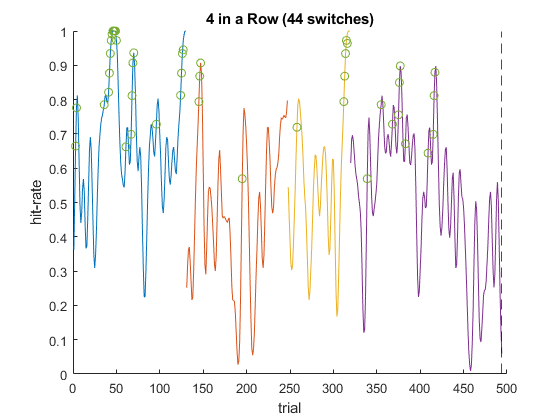

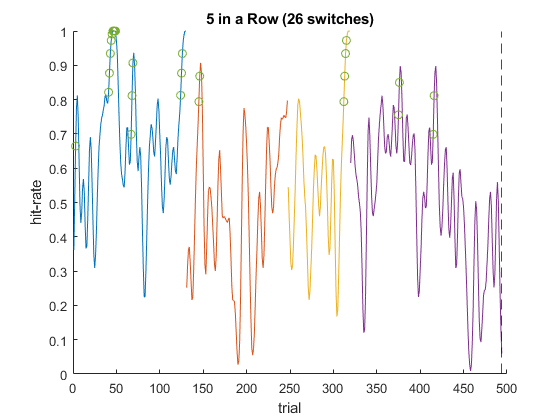

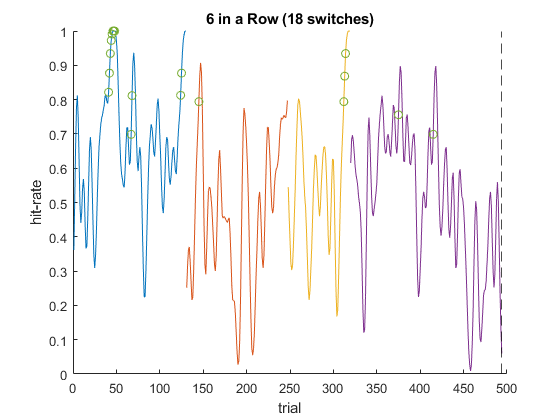

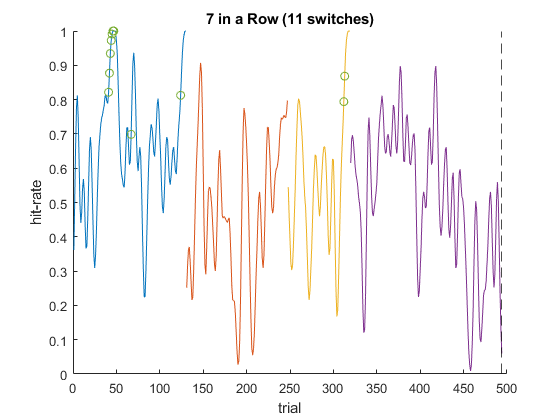

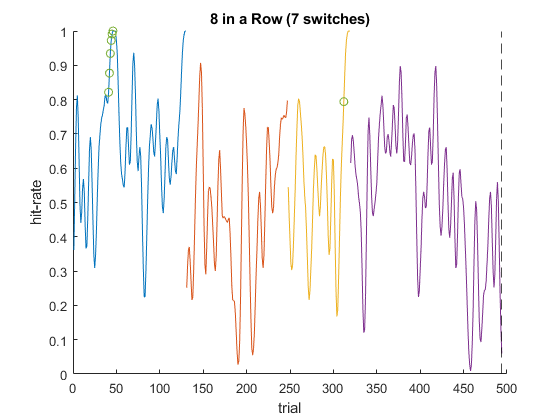

% Analysis of potential switch criteria

% Proposal 1: n in a row
for window = 4:8
    B = multi_day_running_HR(official, 10);
    switches = strfind(official.trials, zeros(1,window));
    scatter(switches, B(switches))
    title([num2str(window) ' in a Row (' num2str(length(switches)) ' switches)'])
end

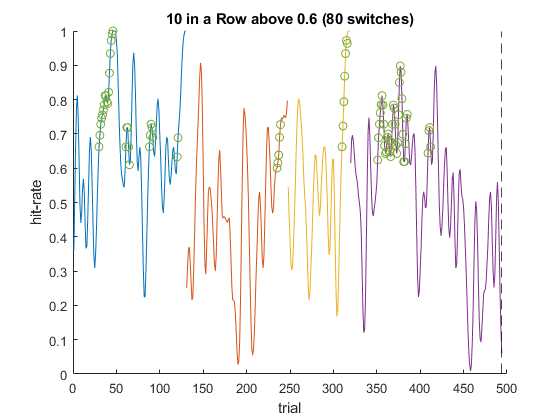

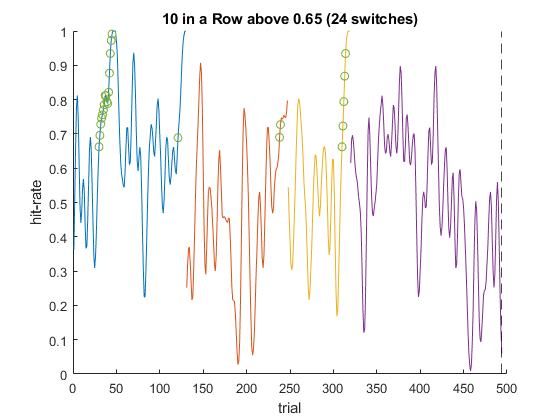

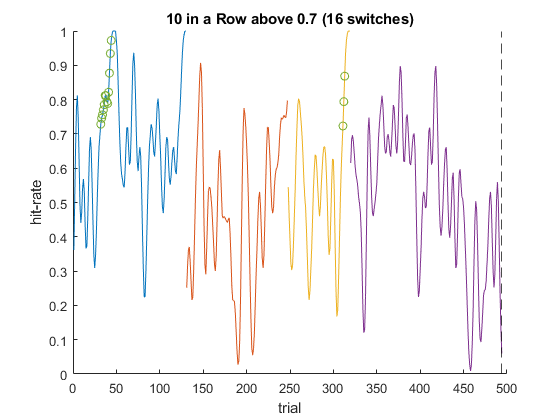

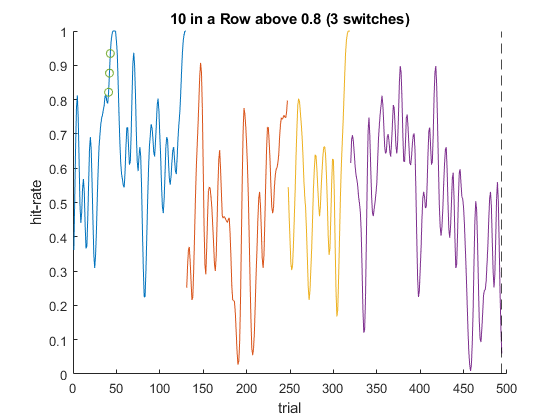

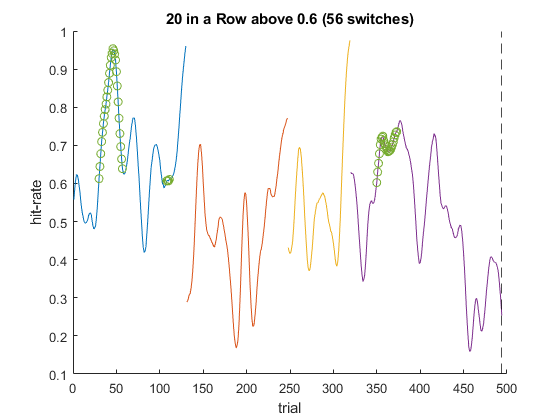

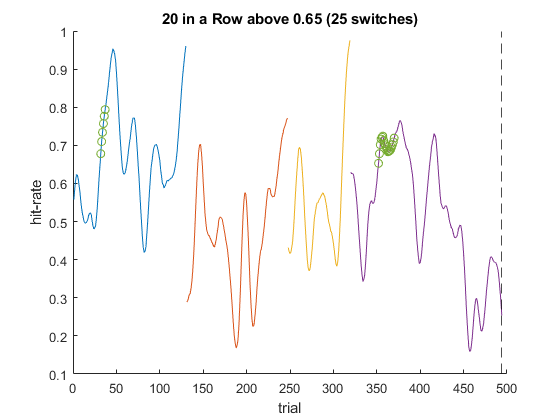

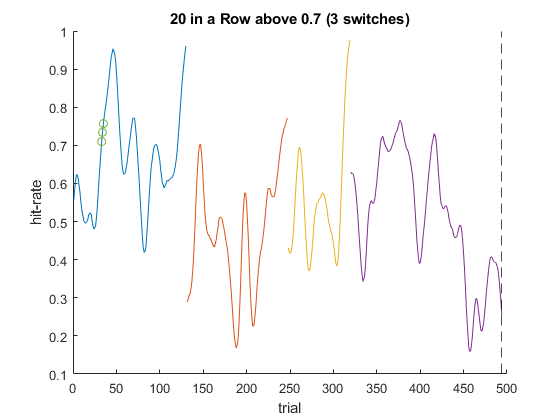

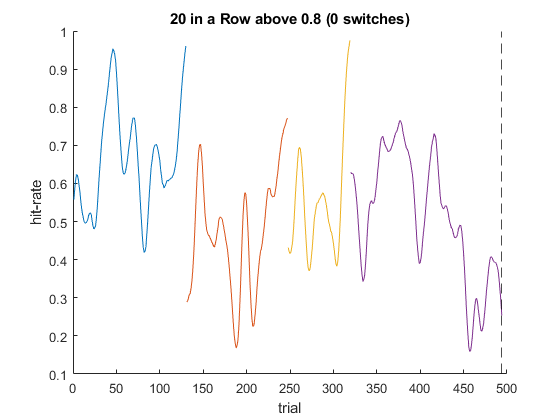


% Proposal 2: sustained performance > threshold HR for n trials
for window = [10 20] % trials
    for threshold = [0.6 .65 0.7 0.8] % hit rate
        B = multi_day_running_HR(official,window);
        above = B>threshold;
        switches = strfind(above, ones(1,window));
        scatter(switches, B(switches))
        title([num2str(window) ' in a Row above ' num2str(threshold) ' (' num2str(length(switches)) ' switches)'])
    end
end

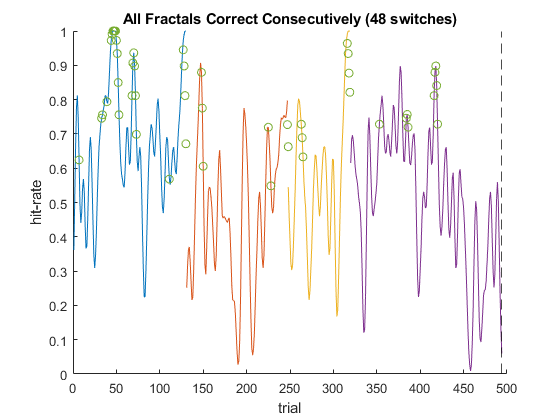


% Proposal 3: all conditions correct
tracker = [0 0 0 0];
switches = [];
for t = 1:length(official.trials)
    if official.trials(t)==0
        tracker(official.fractal(t)) = 1;
    else
        tracker(official.fractal(t)) = 0;
    end
    
    if isequal(tracker, [1 1 1 1])
        switches = [switches t];
    end
end
B = multi_day_running_HR(official, 10);
scatter(switches, B(switches))
title(['All Fractals Correct Consecutively (' num2str(length(switches)) ' switches)'])

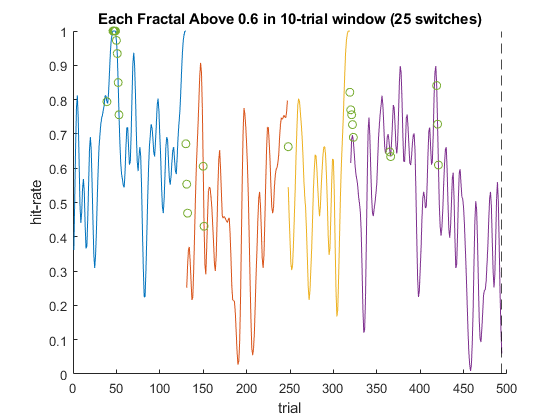

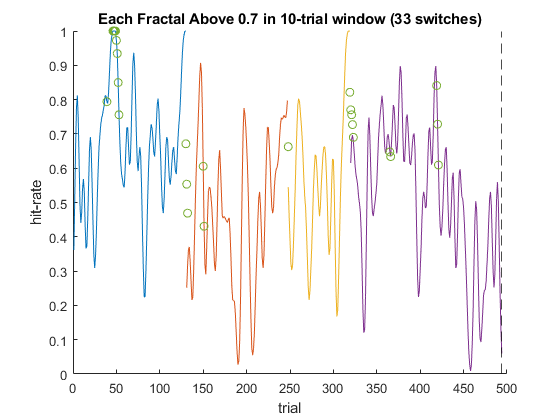

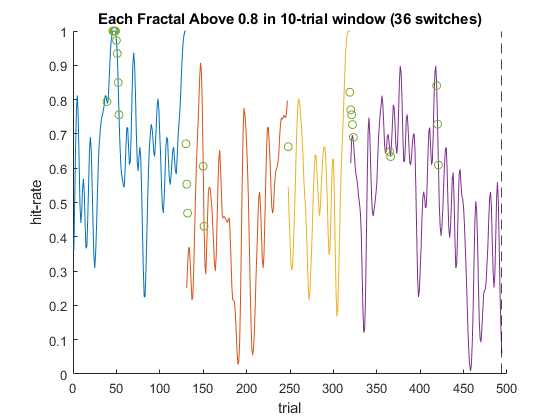

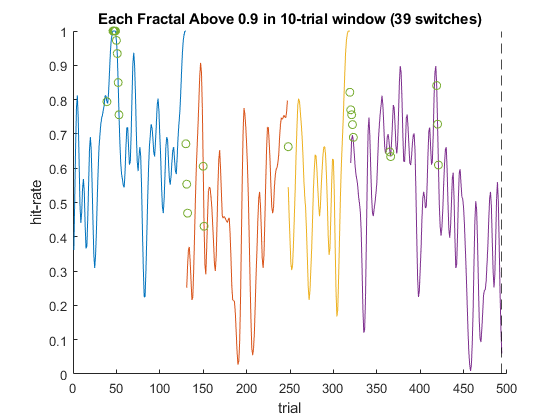

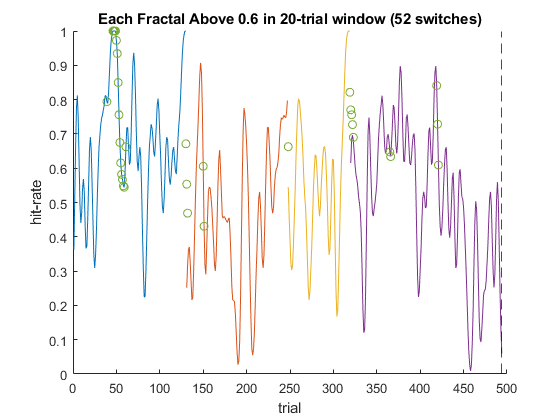

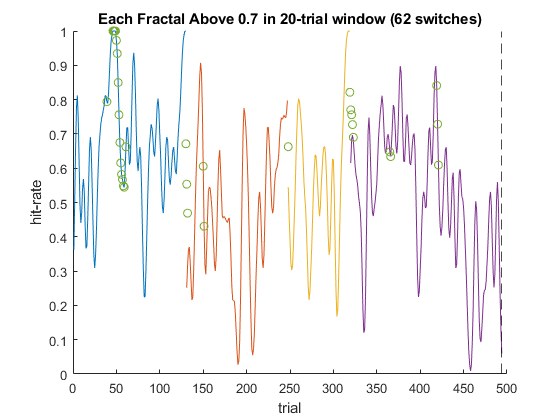

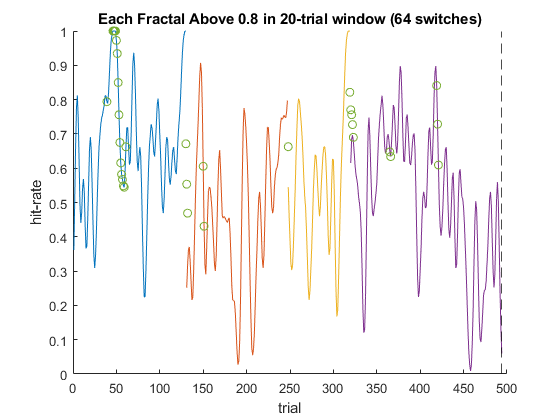

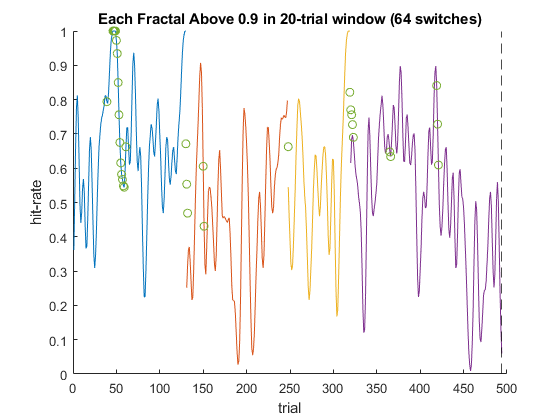


% Proposal 4: each fractal > threshold in n trial-window
switches = [];
for window = [10 20 30] % trials
    for threshold = [0.6 0.7 0.8 0.9] % hit rate
        for t = window+1:length(official.trials)
            window_trials = official.trials(t-window:t);
            A = official.fractal(t-window:t)==1;
            B = official.fractal(t-window:t)==2;
            C = official.fractal(t-window:t)==3;
            D = official.fractal(t-window:t)==4;
            window_HR = [hit_rate_2(window_trials(A)), hit_rate_2(window_trials(B)), hit_rate_2(window_trials(C)), hit_rate_2(window_trials(D))];
            
            if isequal(window_HR>threshold, [1 1 1 1])
                switches = [switches t];
            end
        end
        
        B = multi_day_running_HR(official,10);
        scatter(switches, B(switches))
        title(['Each Fractal Above ' num2str(threshold) ' in ' num2str(window) '-trial window (' num2str(length(switches)) ' switches)'])
    end
end